fs = 44100;
T = 6*0.001;
t = 2.5*0.001;
time = 3;
A = 0.7;
x = linspace(0,T, T*fs);



x0 = linspace(0,time, time*fs)

x0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


y0 = Func(x0,T,t,A)

y0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


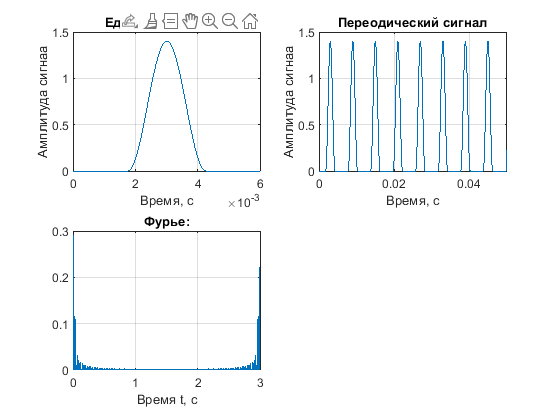



subplot(2,2,1)
plot(x,Func(x,T,t, A))
grid on
title('Единичный сигнал')
xlabel('Время, с')
ylabel('Амплитуда сигнаа')


subplot(2,2,2)
plot(x0,y0)

grid on
title('Переодический сигнал')
xlabel('Время, с')
ylabel('Амплитуда сигнаа')
xlim([0 0.05]);
ylim([0 1.5]);


subplot(2,2,3)
S = abs(fft(y0));
plot(x0, S / (fs*time))

xlim([0 time])
title('Фурье:')
xlabel('Время t, с')
grid on

set(gcf, 'Visible', 'on');